# MECH 6318 - Homework 7

**Name:** Jonas Wagner

**Date:** 2021-10-28

close all
clear

## Problem 6.14

d = 360; % mm (assuming mm)
x_min = 5;   % mm^2
x_max = 200; % mm^2
LB = x_min * ones(10,1);
UB = x_max * ones(10,1);
x_0 = (x_min + x_max)/2 * ones(10,1);
F = 2e3 * ones(8,1); % kN (10^3)

### Part 1

% Volume Cost Function
V = @(X) d * [ones(1,6), sqrt(2) * ones(1,4)] *  X

V = function_handle with value:
    @(X)d*[ones(1,6),sqrt(2)*ones(1,4)]*X

% Minimize Volume
[x_minV, f_minV] = fmincon(V, x_0, [],[],[],[], LB, UB, @nonlinconst)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x_minV =     5.0000
    5.0000
    5.0000
    5.0000
    5.0000
    5.0000
    5.0000
    5.0000
    5.0000
    5.0000


f_minV = 2.0982e+04

### Part 2

% Max Deflection Cost Function
U_max = @(X) max(K(X) \ F)

U_max = function_handle with value:
    @(X)max(K(X)\F)

% Minimize Max Deflection
[x_minUmax, f_minUmax] = fmincon(U_max, x_0, [],[],[],[], LB, UB, @nonlinconst)


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x_minUmax =   199.7356
  194.9814
  199.7388
  199.8610
  171.8078
  156.2883
  199.8603
  199.1830
   94.9827
   68.8680


f_minUmax = 0.0467

### Part 3

options = optimoptions('paretosearch','PlotFcn','psplotparetof');
[x_star, f_star] = paretosearch(@(X) [V(X'); U_max(X')], 10, [],[],[],[],LB,UB,@nonlinconst,options);


Pareto set found that satisfies the constraints. 

Optimization completed because the relative change in the volume of the Pareto set 
is less than 'options.ParetoSetChangeTolerance' and constraints are satisfied to within 
'options.ConstraintTolerance'.



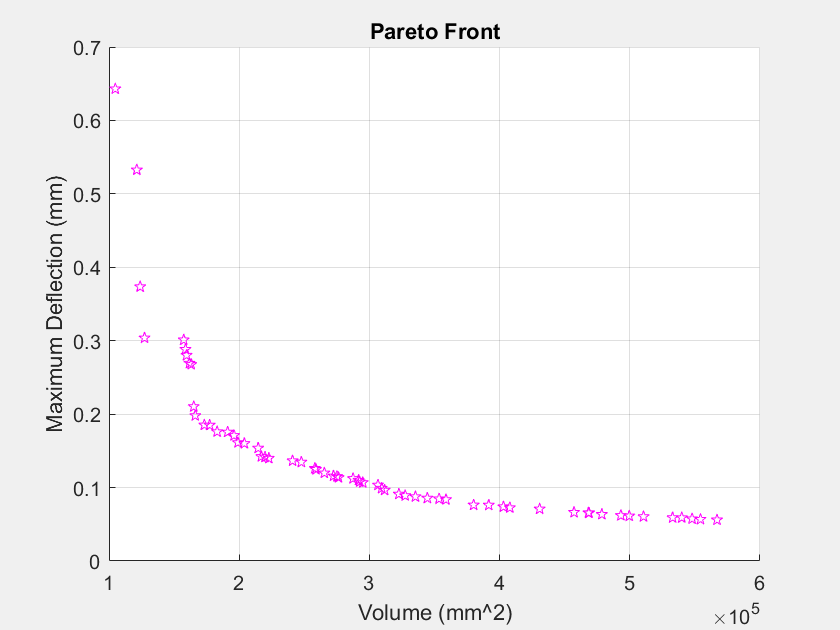

xlabel('Volume (mm^2)')
ylabel('Maximum Deflection (mm)')

## Problem 19.6

% Problem Data
x = [100,  50, 300, 350, 150];
y = [350, 100, 150, 300, 250];
n = length(x);


### Part 1

[x_star1, f_star1] = ga(@obj, n, [], [], [], [],...
                        ones(1,5), 5*ones(1,5), @const, [1:5])

Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
but constraints are not satisfied.


x_star1 =      3     4     2     3     5


f_star1 = 1.2088e+03

### Part 2

[x_star2, f_star2] = ga(@obj2, n, [], [], [], [],...
                        ones(1,5), 5 * ones(1,5), @const, [1:5])

Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.


x_star2 =      5     2     3     4     1


f_star2 = 1.0978e+03

## Functions

### Problem 6.14 Functions

function [K] = K(x)
    E = 2e5;
    d = 360;
    z = 2*sqrt(2);
    K_a = [
            x(1) + x(2) + (x(8) + x(9))/z,  (-x(8) + x(9))/z,   -x(2),  0;
            (-x(8) + x(9))/z,   x(5) + (x(8)+x(9))/z,   0,  0;
            -x(2),  0,  x(2) + x(10)/z, -x(10)/z;
            0,  0,  -x(10)/z,   x(6) + x(10)/z;
            -x(9)/z,    -x(9)/z,    0,  0;
            -x(9)/z,    -x(9)/z,    0,  x(6);
            0,  0,  -x(10)/z,   x(10)/z;
            0,  -x(5),  x(10)/z,    -x(10)/z
            ];
    K_b = [
            -x(9)/z,    -x(9)/z,    0,  0;
            -x(9)/z,   -x(9)/z,    0,  -x(5);
            0,  0,  -x(10)/z,   x(10)/z;
            0,  -x(6),  x(10)/z,    -x(10)/z;
            x(4) + x(9)/z,  x(9)/z, -x(4),  0;
            x(9)/z, x(6) + x(9)/z,  0,  0;
            -x(4),  0,  x(3) + x(4) + (x(7) + x(10))/z, (x(7) - x(10))/z,
            0,  0,  (x(7)-x(10))/z, x(5) + (x(7) + x(10))/z
            ];
    K = E/d * [K_a, K_b];
end

function [c,ceq] = nonlinconst(X)
    u_min = -15; % mm
    u_max = 15;  % mm
    sigma_min = -150; % N /mm^2
    sigma_max = 150;  % N /mm^2
    F = 2e3 * ones(8,1); % kN (10^3)
    
S = [   1   0   0   0   0   0   0   0;
       -1   0   1   0   0   0   0   0;
        0   0   0   0   0   0   1   0;
        0   0   0   0   1   0  -1   0;
        0  -1   0   0   0   0   0   1;
        0   0   0  -1   0   1   0   0;
        0   0   0   0   0   0   0.5 0.5;
       0.5 -0.5 0   0   0   0   0   0;
      -0.5 -0.5 0   0 0.5 0.5   0   0;
        0   0  0.5 -0.5 0   0 -0.5  0];    
    
    
    c = [
        sigma_min - S / K(X) * F; % sigma_min \leq sigma = S * K^{-1} * F
        S / K(X) * F - sigma_max; % sigma = S * K^{-1} * F \leq sigma_max
        u_min - K(X) \ F; % u_min \leq u = K^{-1} * F
        K(X) \ F - u_max % u = K^{-1} * F \leq u_max
        ];
    ceq = [];
end

### Problem 19.6 Functions

function J = obj(X)
    x = [100,  50, 300, 350, 150];
    y = [350, 100, 150, 300, 250];
    J = 0;
    next = [x(X(1)),y(X(1))];
    for idx = X
        current = next;
        next = [x(X(idx)),y(X(idx))];
        J = J + norm(next-current,2);
    end
end

function J = obj2(X)
    J = obj([X, X(1)]);
end


function [num,c] = const(X)
        n=5;
        inter = intersect(X,(1:n));
        num = (500*(n - length(inter)))^2;
        c = [];
end




